First, let's state the data series we'll be using; for jsd tests, it should be one of 1,7,8 or 10


clear variables;

dataSeriesId = 10;
[shortname,fullname] = data_set_info(dataSeriesId);

data = get_small_data_set( shortname );
data = L1Normalise(data);

[shep_dim, red_dims] = data_set_misc_info( shortname );


So grab a couple of thousand random values from the data into two separate collections...


witnessSize = 1000;
dataSize = 1000;

randIds = getRandomIds(witnessSize + dataSize, size(data,1));

witnesses = data(randIds(1:witnessSize),:);
data = data(randIds(witnessSize + 1 : witnessSize + dataSize),:);

clear randIds;

Now we'll create the reduction transforms: lmds and nsimplex

Shepard plots and Kruskal stress (displayed on plot), using Jensen-Shannon distance

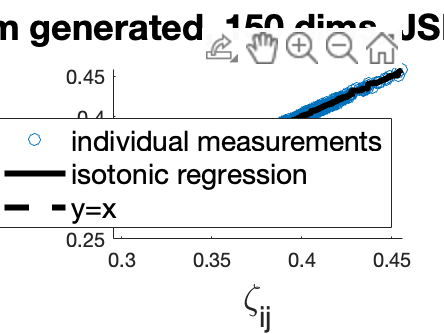

%shepardReductionDimension has been set at the start depending on data set
%but can be overridden to show different typically smaller reductions...

shep_dim = 150;

nsimpP = NsimpProjection(witnesses, shep_dim, @jsd);
lmdsP = LmdsProjection(witnesses, shep_dim, @jsd);

nsimpProj = zeros(size(data,1),shep_dim);
lmdsProj = zeros(size(data,1),shep_dim);
%maybe change the projection classes to do bulk operations! but not really
%an efficiency problem here...
for i = 1 : size(data,1)
    nsimpProj(i,:) = nsimpP.project(data(i,:));
end

for i = 1 : size(data,1)
    lmdsProj(i,:) = lmdsP.project(data(i,:));
end

expTitle = strcat( fullname,", ", int2str(shep_dim)," dims, JSD");

noOfPointsForPlots = 50;
firstNPoints = data(1:noOfPointsForPlots,:);

shepard(pdist(firstNPoints,@jsd),pdist(nsimpProj(1:noOfPointsForPlots,:),@zen),strcat("Zen: ",expTitle));

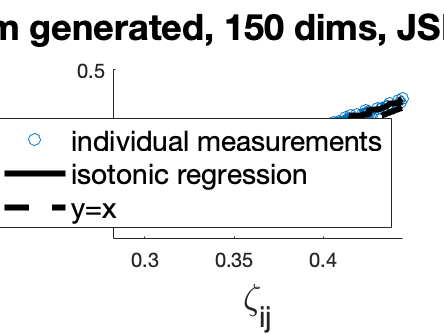

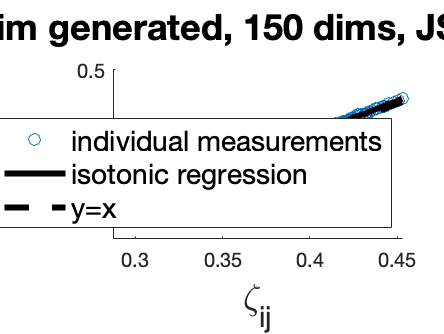

shepard(pdist(firstNPoints,@jsd),pdist(lmdsProj(1:noOfPointsForPlots,:)),strcat("LMDS: ", expTitle));


trueDists = pdist(data,@jsd);
zenDists = pdist(nsimpProj,@zen);
lmdsDists = pdist(lmdsProj);

zk = kruskal(trueDists,zenDists)

zk = 0.0146

lk = kruskal(trueDists,lmdsDists)

lk = 0.0034


zs = sammon(trueDists,zenDists)

zs = 2.5510e-04

ls = sammon(trueDists,lmdsDists)

ls = 4.8727e-04


zr = spearman_rho(trueDists,zenDists)

zr = 0.9702

lr = spearman_rho(trueDists,lmdsDists)

lr = 0.9986

Now let's plot various quality metrics against reduction dimension...


zKruskal = zeros(1,size(red_dims,2));
zSpearman = zeros(1,size(red_dims,2));
zSammon = zeros(1,size(red_dims,2));
zQuadLoss = zeros(1,size(red_dims,2));
mKruskal = zeros(1,size(red_dims,2));
mSpearman = zeros(1,size(red_dims,2));
mSammon = zeros(1,size(red_dims,2));
mQuadLoss = zeros(1,size(red_dims,2));

for i = 1 : size(red_dims,2)
    projDim = red_dims(i);
    
    nsimpP = NsimpProjection(witnesses(1:max(500,projDim+1),:),projDim,@jsd);
    nsimpProj = zeros(size(data,1),projDim);
    
    mdsP = LmdsProjection(witnesses(1:max(200,projDim+1),:),projDim, @jsd);
    mdsProj = zeros(size(data,1),projDim);
    disp(projDim);
    
    
    for j = 1 : size(data,1)
        nsimpProj(j,:) = nsimpP.project(data(j,:));
        mdsProj(j,:) = mdsP.project(data(j,:));
    end
    
    trueDists = pdist(data, @jsd);
    zenDists = pdist(nsimpProj,@zen);
    mdsDists = pdist(mdsProj);
    
    zKruskal(i) = 1 - kruskal(trueDists,zenDists);
    zSpearman(i) = spearman_rho(trueDists,zenDists);
    zSammon(i) = 1 - sammon(trueDists,zenDists);
    mKruskal(i) = 1 - kruskal(trueDists,mdsDists);
    mSpearman(i) = spearman_rho(trueDists,mdsDists);
    mSammon(i) = 1 - sammon(trueDists,mdsDists);
    
    zQuadLoss(i) = quadratic_loss(trueDists,zenDists);
    mQuadLoss(i) = quadratic_loss(trueDists,mdsDists);
end

   100

    90

    80

    70

    60

    50

    40

    30

    20

    15

    10

     5

     3

     2



m = -100

x = 20

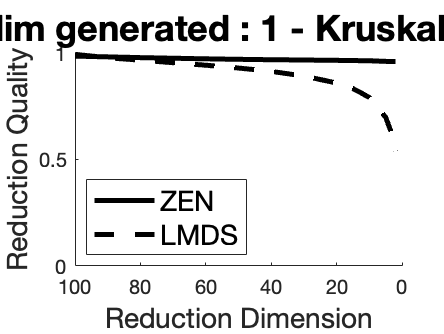


plotChartJsd(red_dims,zKruskal,mKruskal,fullname,1);

m = -100

x = 20

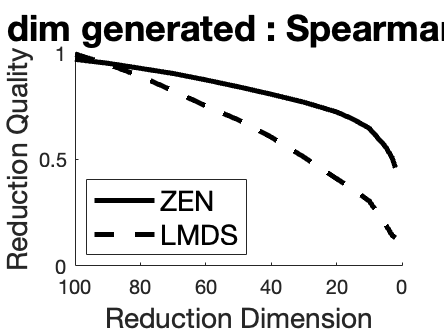

plotChartJsd(red_dims,zSpearman,mSpearman,fullname,2);

m = -100

x = 20

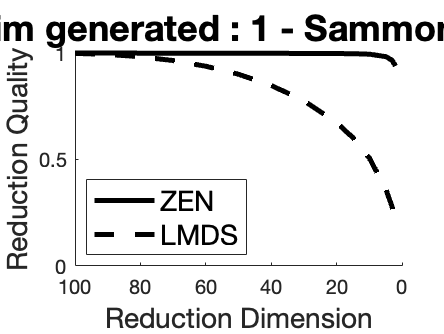

plotChartJsd(red_dims,zSammon,mSammon,fullname,3);

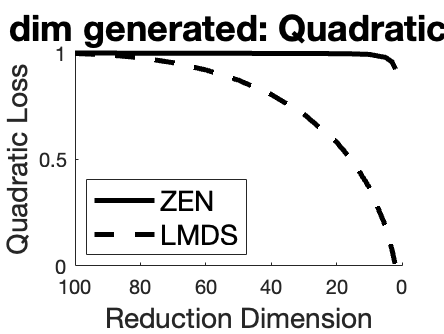

plotQuadLossJsd(red_dims,zQuadLoss,mQuadLoss,fullname);